# Calibraiton of feeder position

function [r_fd_new,r_fd_old] = r_feeder_calibrate(datadir)

This function calculates the coordinate of feeders in the flight room. The coordinate of the corners and the center of each feeder were recorded using 5 tags. The serial number of the tags used for acquiring coordinates is here:

- Left, rear (close to the center of the room) corner: 17106917 (Tag_1)

- Left, front (close to the wall) corner: 17106926 (Tag_2)

- Right, front: 17107055 (Tag_3)

- Right, rear: 17106969 (Tag_4)

- Center (on the virtual line between beem emitter & detecter): 17106904 (Tag_5)

            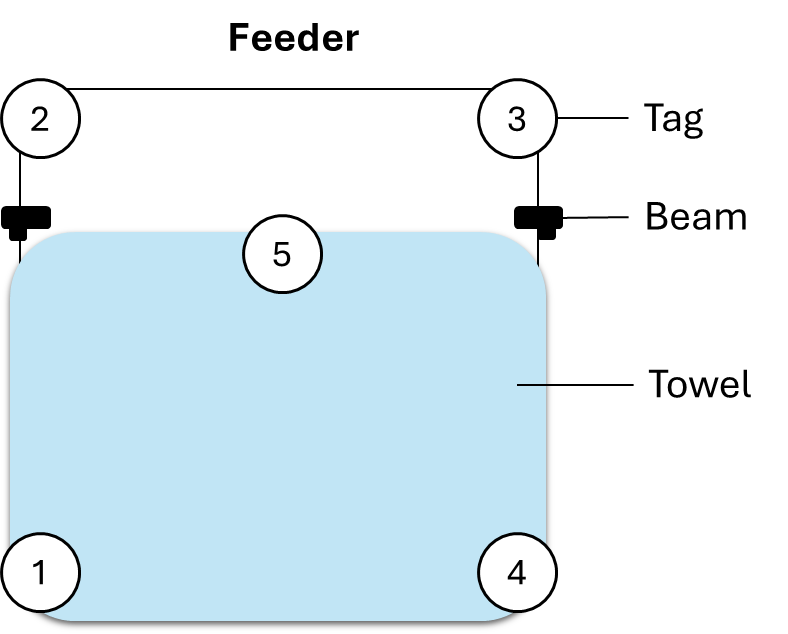

### Input

- datadir: directory of cdp data for calibration recordings

% datadir = 'Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration'; % directory of calibration recordings

### Output

- r_fd_new: coordinate of feeders in the flight room

### Main

% Extract data
nowdir = pwd; % current directory
try
    datapath = dir(fullfile(datadir,'*cdp*calibration*'));
    SN = dir(fullfile(datadir,'*Serial*.txt')); SN = load(fullfile(SN.folder,SN.name)); % list of serial number
    for dd = 1:length(datapath)
        
        outdir = fullfile(datadir,sprintf('feeder%d',dd)); % output directory
        if isempty(dir(outdir))
            mkdir(outdir);        mkdir(fullfile(outdir,'figure'))
        end

        cd(datapath(dd).folder);    
        if isempty(dir(fullfile(outdir,'extracted*cdp*')))
            ExtractCdp_AF_TY_v2(sprintf('cdp*feeder%d',dd),outdir,'Include',SN') % Extract
        end

        cd(outdir);
        if isempty(dir(fullfile(outdir,'*Ext_Behavior*')))
            Process_extracted_cdp_TY_v0(outdir) % Analyze
        end
        close all
    end
catch ME
    cd(nowdir)
    rethrow(ME)
end
cd(nowdir)

% Visualize the position of tags
% figure
% set(gcf,'units','normalized','position',[0.1,0.3,0.6,0.25])
% tiledlayout(1,4,'TileSpacing','tight')
% 
% beh_dir = dir(fullfile(datadir,'*feeder*','Ext_Behavior*','Extracted_Behavior*'));
% for dd = 1:length(beh_dir)
%     load(fullfile(beh_dir(dd).folder,beh_dir(dd).name),'r','r_lim')
%     r_med = squeeze(median(r,1))'; % median location of each tag
% 
%     nexttile
%     hold on
%     scatter(r_med(5,1),r_med(5,2),20,'.k')
%     plot([r_med(1:4,1);r_med(1,1)],[r_med(1:4,2);r_med(1,2)],'k')
%     hold off
%     xlim(r_lim(1,:))
%     ylim(r_lim(2,:))
% end

% compute the coordinate of tags
r_fd_old = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % coordinate computed by someone (Angelo?)
r_fd_new = zeros(4,3);
beh_dir = dir(fullfile(datadir,'*feeder*','Ext_Behavior*','Extracted_Behavior*'));
for dd = 1:length(beh_dir)
    load(fullfile(beh_dir(dd).folder,beh_dir(dd).name),'r')
    r_fd_new(dd,:) = median(r(:,:,5),1); % median location of tag 5 on each feeder
    % norm(r_fd_old(dd,:)-r_fd_new(dd,:))
end

end